clearvars; clc;

# Esercitazione 2

#### Definizioni

s=tf('s');
Gcont=160/(s^2+36*s+400);

Definisco il sistema discretizzato

Ts=0.01;
G=zpk(c2d(Gcont,Ts,'zoh'))


G =
 
   0.0070974 (z+0.8869)
  -----------------------
  (z^2 - 1.664z + 0.6977)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.


### Studio requisiti

[z_G, p_G, k_G]=zpkdata(G,'v')

z_G = -0.8869

p_G =    0.8321 + 0.0727i
   0.8321 - 0.0727i


k_G = 0.0071

B=k_G*[1 -z_G]; %numeratore di G scritto come matrice polinomiale
A=conv([1 -p_G(1)],[1 -p_G(2)]);

G1=dcgain(G);
nadd=1;
l1=0;
l2=1;
l=l1+l2;

- Kc >= 0.25

- Already satisfied because system must be type 0 but it's already type 1

s_hat=0.19;
t_s1=1;
zeta=abs(log(s_hat))/sqrt(pi^2+log(s_hat)^2)

zeta = 0.4673

wn=4.6/(zeta*t_s1)

wn = 9.8428

#### Damping area

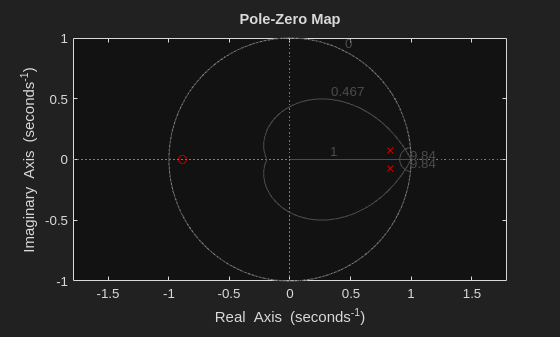

set(gcf,'Visible','on');
pzmap(G,'r');
axis('equal');
hold on
zgrid(zeta,wn,Ts)

#### Pole allocation

Aplus=A;
Aminus=1;
Bplus=1;
Bminus=B;

deg_A=2;
deg_B=1;
deg_A1=deg_A;
deg_Aplus=deg_A;
deg_Aminus=0;
deg_Bplus=0;
deg_Bminus=deg_B;

deg_S1=l+deg_Aminus-1+nadd

deg_S1 = 1

deg_R2=deg_A1-deg_Bplus+l1-1+nadd

deg_R2 = 2

deg_Am=l+deg_A1+deg_Aminus+l1-deg_Bplus-1+nadd

deg_Am = 3


p1c=-zeta*wn+1i*wn*sqrt(1-zeta^2);
p1=exp(p1c*Ts);
p2=conj(p1);
p3c=-5*zeta*wn;
p3=exp(p3c*Ts);

A_dioph=conv(Aminus,[1 -1])

A_dioph =      1    -1


B_dioph=Bminus

B_dioph =     0.0071    0.0063


Gamma=[poly([p1 p2 p3])';0];
M_s=[[A_dioph 0 0]' [0 A_dioph 0]' [0 0 A_dioph]' [0 B_dioph 0]' [0 0 B_dioph]';-10*Ts*polyval(Bplus,1)*ones(1,3) polyval(Aplus,1)*G1*ones(1,2)];
theta=M_s\Gamma;

R2=theta(1:3,:);
S1=theta(4:5,:);

R=conv(Bplus,conv([1 -1],R2))';
S=conv(Aplus,S1);

C=zpk(tf(S,R,Ts))


C =
 
  0.68688 (z-0.7934) (z^2 - 1.664z + 0.6977)
  ------------------------------------------
         (z-1) (z-0.9073) (z-0.7949)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.


#### Simulation

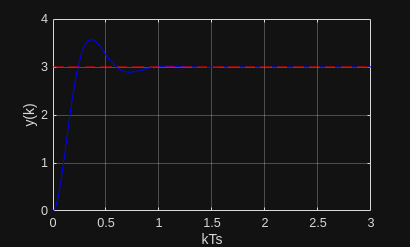

t_sim=3;

r=3;
delta_d2=0;

out=sim("sim_esercitazione_2");

y=out.y;

figure;
plot(y.time,y.data,'b',y.time,r*ones(y.Length,1),'--r'), grid on, xlabel('kTs'),ylabel('y(k)');

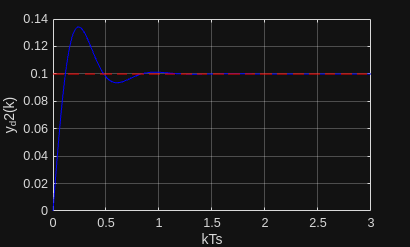


r=0;
delta_d2=1;

out=sim("sim_esercitazione_2");

y=out.y;

figure;
plot(y.time,y.data,'b',y.time,0.1*ones(y.Length,1),'--r'), grid on, xlabel('kTs'),ylabel('y_d2(k)');